# Topic 2: Rocket landing problem

## Variables

clear -except folder 

folder = '/Users/sebastianozuddas/Programming/Latex/ACS6116---Rocket-Landing-MPC-/Figures/new';


T = 0.5;
I = eye(3);
zero = zeros(3);% zero matrix
mass = 1; % mass of rocket (kg)

g = 9.81;% gravitational constant 

A = [I T*I; zero I];
B = ((1/mass)*[0.5*T^2*I; T*I]);
C = eye(width(A));
D = zeros(height(B),width(B));

% Weighting matrices

Q = [100 0 0 0 0 0;%rx
     0 100 0 0 0 0;%ry
     0 0 5 0 0 0;%rz
     0 0 0 1 0 0;%vx
     0 0 0 0 1 0;%vy
     0 0 0 0 0 100]%vz

Q =    100     0     0     0     0     0
     0   100     0     0     0     0
     0     0     5     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0   100


R = eye(3)*0.1;

n = size(A, 2);
m = size(B, 2);
p = size(C, 1);
N = 5 % Horizon

N = 5


%K_inf = dlqr(A, B, Q, R)
K_2 = -place(A, B, [0.01 0.01 0 0.01 0 0])

K_2 =    -3.9600         0         0   -2.9900         0         0
         0   -3.9600         0         0   -2.9900         0
         0         0   -3.9600         0         0   -2.9900



P = dlyap((A+B*K_2)', Q+K_2'*R*K_2);
% prediction matrices
[F, G] = predict_mats(A, B, N);

% cost funciton matrices
[H, L, M] = cost_mats(F, G, Q, R, P);

% unconstrained control law
S = -H\L; % left divide note the backslash
% gives m*N by n 

KN = S(1:m, :);% unconstrained control law
% could also be done with Ricatti

%Initial States
r0 = [600 600 500]';
v0 = [5 5 -15]'; % velocity
x0 = [r0; v0]; % Initial state (position and velocity)
u0 = zeros(3, 1);% initial inputs 

% check stability of A+B*KN
eig(A+B*KN);

spectral_radius = max(abs(eig(A+B*KN)));
sr = spectral_radius

sr = 0.8152


if sr>= 1
    disp('KN not stabilising')
else 
    disp('KN stabilising')
end

KN stabilising





time_steps = 100

time_steps = 100

## Unconstrained

% Initial States
% rand_distance = rand_3d_vec(600, 500)
r0 = [600 600 500]';
v0 = [5 -5 -15]'; % velocity
x0 = [r0; v0]; % Initial state (position and velocity)
u0 = zeros(3, 1);% initial inputs 

k = 1;
x = x0

x =    600
   600
   500
     5
    -5
   -15


u = u0;


while k<=100

    Uopt = quadprog(H, L*x); %get the optimal control sequence
    uopt = Uopt(1:m, :); % extract the first m from that sequence
    x = A*x + B*(uopt);
    k = k + 1;    
    xs(:, k) = x;
    us(:, k) = uopt;

end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because

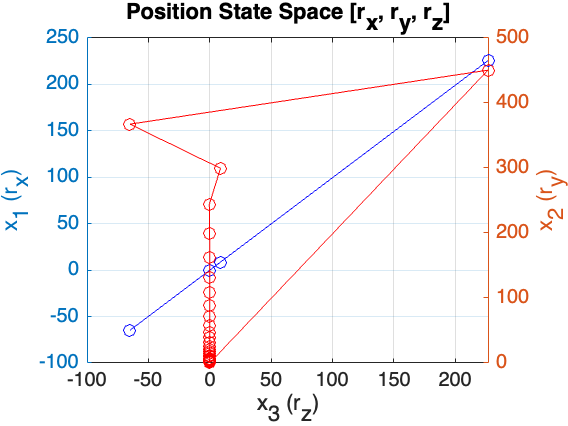


figure% Position States
yyaxis left
plot(xs(1,:), xs(2, :),'bo-')
ylabel('x_1 (r_x)')
yyaxis right
plot(xs(1,:), xs(3, :), 'ro-')
grid on
xlabel('x_3 (r_z)')
ylabel('x_2 (r_y)')
title('Position State Space [r_x, r_y, r_z]')

figure_name = 'Unconstrained_position_state_space'; % You can change this to your desired figure name
full_path = fullfile(folder, figure_name);
saveas(gcf, full_path, 'png'); % 'png' is the file format, you can use other formats like 'jpg', 'pdf', 'fig', etc.

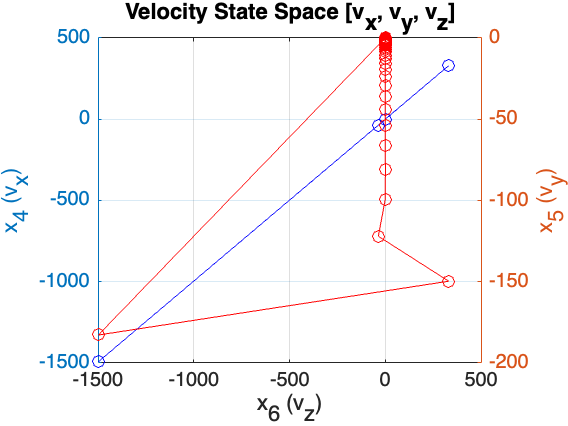



figure% Velocity States
yyaxis left
plot(xs(4,:), xs(5, :),'bo-')
ylabel('x_4 (v_x)')

yyaxis right
plot(xs(4,:), xs(6, :), 'ro-')
grid on
xlabel('x_6 (v_z)')
ylabel('x_5 (v_y)')
title('Velocity State Space [v_x, v_y, v_z]')
figure_name = 'Unconstrained_velocity_state_space'; % You can change this to your desired figure name
full_path = fullfile(folder, figure_name);
saveas(gcf, full_path, 'png'); % 'png' is the file format, you can use other formats like 'jpg', 'pdf', 'fig', etc.

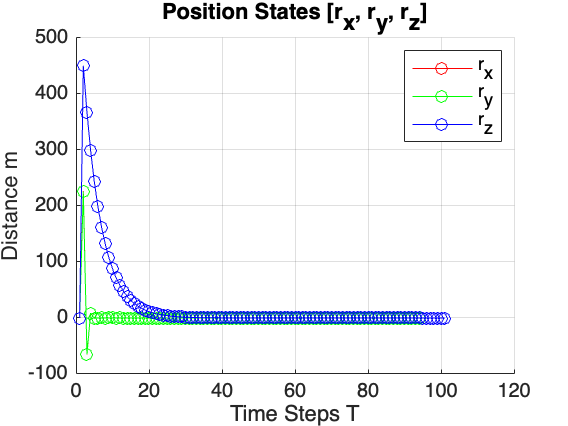


figure
hold on
grid on
plot(xs(1,:), 'ro-')
plot(xs(2,:), 'go-')
plot(xs(3,:), 'bo-')

legend('r_x', 'r_y', 'r_z')
title('Position States [r_x, r_y, r_z]')
ylabel('Distance m')
xlabel('Time Steps T')
hold off
figure_name = 'Unconstrained_position_state_plot'; % You can change this to your desired figure name
full_path = fullfile(folder, figure_name);
saveas(gcf, full_path, 'png'); % 'png' is the file format, you can use other formats like 'jpg', 'pdf', 'fig', etc.

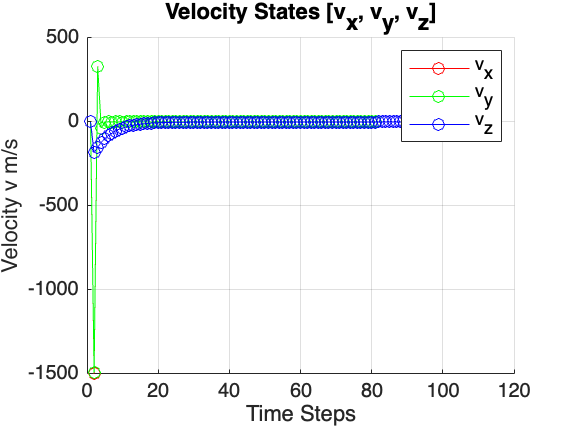


figure 
hold on
grid on
plot(xs(4,:), 'ro-')
plot(xs(5,:), 'go-')
plot(xs(6,:), 'bo-')

legend('v_x', 'v_y', 'v_z')
title('Velocity States [v_x, v_y, v_z]')
ylabel('Velocity v m/s')
xlabel('Time Steps')
hold off
figure_name = 'Unconstrained_velocity_state_plot'; % You can change this to your desired figure name
full_path = fullfile(folder, figure_name);
saveas(gcf, full_path, 'png'); % 'png' is the file format, you can use other formats like 'jpg', 'pdf', 'fig', etc.

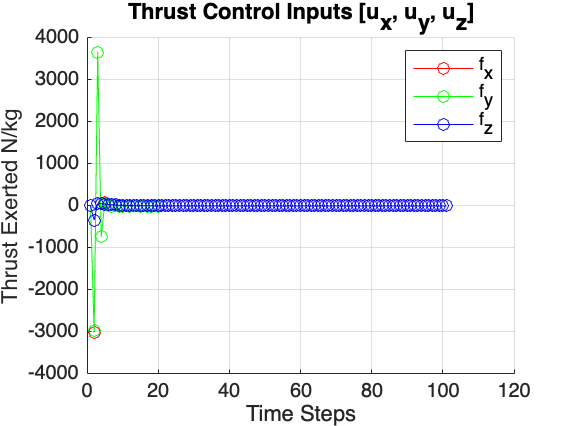


figure
hold on
grid on
plot(us(1,:), 'ro-')
plot(us(2,:), 'go-')
plot(us(3,:), 'bo-')

legend('f_x', 'f_y', 'f_z')
title('Thrust Control Inputs [u_x, u_y, u_z]')
ylabel('Thrust Exerted N/kg')
xlabel('Time Steps')
hold off

figure_name = 'Unconstrained_input_plot'; % You can change this to your desired figure name
full_path = fullfile(folder, figure_name);
saveas(gcf, full_path, 'png'); % 'png' is the file format, you can use other formats like 'jpg', 'pdf', 'fig', etc.

## Constrained

%Initial States
r0 = [600 600 500]';
v0 = [0 0 -15]'; % velocity
x0 = [r0; v0]; % Initial state (position and velocity)
u0 = zeros(3, 1);% initial inputs 

% Rocket state and control input initialization
x = x0;
u = u0;
rxy_max = (500/tan(deg2rad(30)))+50

rxy_max = 916.0254

% State Constraints
xmax = [rxy_max; rxy_max; 500; 20; 20; 15];% 500m distance, 15m/s fastest z, 20m/s fastest (x,y)
xmin = [-rxy_max; -rxy_max; 0; -20; -20; -15];
Px = [eye(n); -eye(n)];
qx = [xmax; -xmin];

% Input constraints
uxy_max = 12*(tan(deg2rad(10)))*4;
umax = [uxy_max ;uxy_max; 12];%fx max, fy max, fz max
umin = [-uxy_max; -uxy_max; 0];% fx min, fy min, fz min
Pu = [eye(m); -eye(m)];
qu = [umax; -umin];

% build constraint matrix for QP
[Pc, qc, Sc] = constraint_mats(F, G, Pu, qu, Px, qx, Px, qx);

k = 1;

while k<=time_steps
    % Disturbances
    w_x = sin(k/50); 
    w_y = cos(k/50);

    Uopt = quadprog(H, L*x, Pc, qc+Sc*x);
    % Check if Uopt is not empty before assigning values
    if isempty(Uopt)
        break
    end
    uopt = Uopt(1:m, :);

    % Update the state with disturbance
    x = A*x + B*(uopt + [w_x w_y 0]');
    %x = A*x + B*([1 0 0 ; 0 1 0; 0 0 1/mass]*uopt + [w_x w_y mass*g]');     %x = A*x + B*([1 0 0 ; 0 1 0; 0 0 1/mass]*uopt);
    %x = A*x + B*(uopt);
    % Collecting Data
    

    xs_c(:, k) = x;
    us_c(:, k) = uopt;
    k = k + 1;
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because

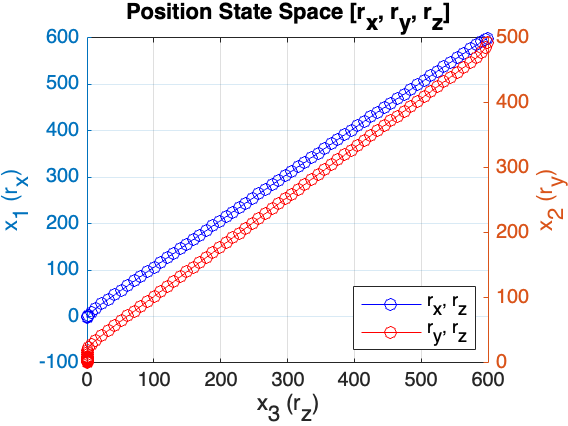


figure% Position States
yyaxis left
plot(xs_c(1,:), xs_c(2, :),'bo-')
ylabel('x_1 (r_x)')

yyaxis right
plot(xs_c(1,:), xs_c(3, :), 'ro-')
grid on
xlabel('x_3 (r_z)')
ylabel('x_2 (r_y)')
legend('r_x, r_z', 'r_y, r_z', location='southeast')
title('Position State Space [r_x, r_y, r_z]')
%maybe put the z axes as the x in both graphs
figure_name = 'Constrained_position_state_space'; % You can change this to your desired figure name
full_path = fullfile(folder, figure_name);
saveas(gcf, full_path, 'png'); % 'png' is the file format, you can use other formats like 'jpg', 'pdf', 'fig', etc.

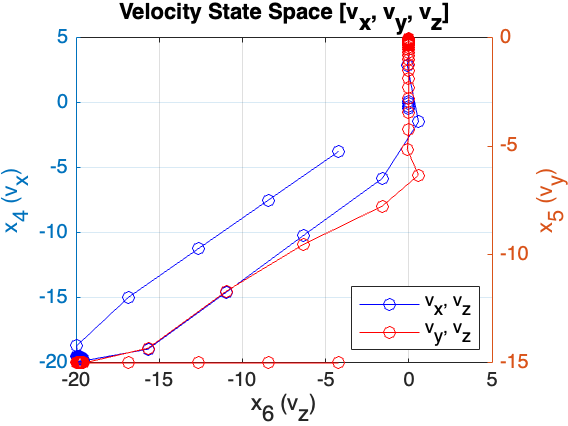


figure% Velocity States
yyaxis left
plot(xs_c(4,:), xs_c(5, :),'bo-')
ylabel('x_4 (v_x)')

yyaxis right
plot(xs_c(4,:), xs_c(6, :), 'ro-')
grid on
xlabel('x_6 (v_z)')
ylabel('x_5 (v_y)')
title('Velocity State Space [v_x, v_y, v_z]')
legend('v_x, v_z', 'v_y, v_z', location='southeast')
figure_name = 'Constrained_position_state_space'; % You can change this to your desired figure name
full_path = fullfile(folder, figure_name);
saveas(gcf, full_path, 'png'); % 'png' is the file format, you can use other formats like 'jpg', 'pdf', 'fig', etc.

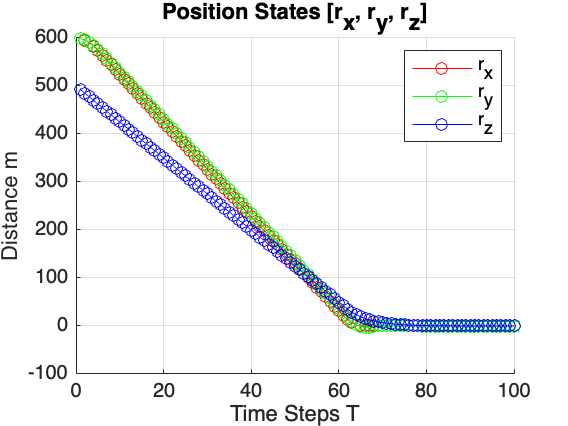


figure
hold on
grid on
plot(xs_c(1,:), 'ro-')
plot(xs_c(2,:), 'go-')
plot(xs_c(3,:), 'bo-')

legend('r_x', 'r_y', 'r_z')
title('Position States [r_x, r_y, r_z]')
ylabel('Distance m')
xlabel('Time Steps T')
hold off
figure_name = 'Constrained_position_state_plot'; % You can change this to your desired figure name
full_path = fullfile(folder, figure_name);
saveas(gcf, full_path, 'png'); % 'png' is the file format, you can use other formats like 'jpg', 'pdf', 'fig', etc.

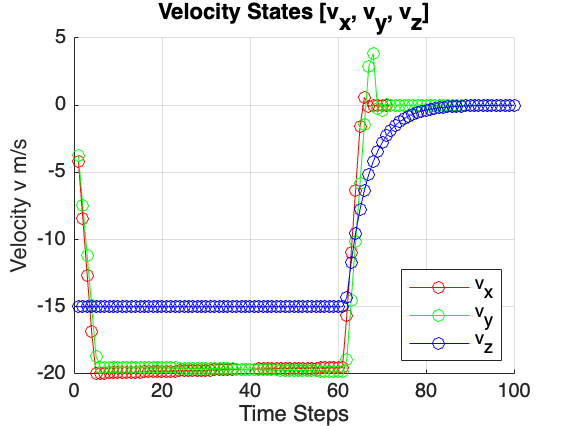


figure 
hold on
grid on
plot(xs_c(4,:), 'ro-')
plot(xs_c(5,:), 'go-')
plot(xs_c(6,:), 'bo-')

legend('v_x', 'v_y', 'v_z', location='southeast')
title('Velocity States [v_x, v_y, v_z]')
ylabel('Velocity v m/s')
xlabel('Time Steps')
hold off
figure_name = 'Constrained_velocity_state_plot'; % You can change this to your desired figure name
full_path = fullfile(folder, figure_name);
saveas(gcf, full_path, 'png'); % 'png' is the file format, you can use other formats like 'jpg', 'pdf', 'fig', etc.

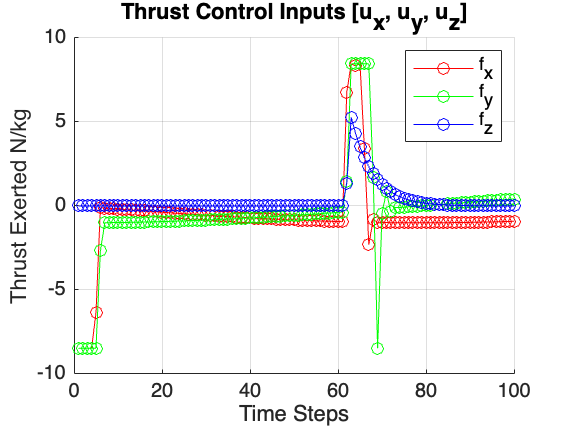


figure
hold on
grid on
plot(us_c(1,:), 'ro-')
plot(us_c(2,:), 'go-')
plot(us_c(3,:), 'bo-')

legend('f_x', 'f_y', 'f_z')
title('Thrust Control Inputs [u_x, u_y, u_z]')
ylabel('Thrust Exerted N/kg')
xlabel('Time Steps')
hold off
figure_name = 'Constrained_input_plot'; % You can change this to your desired figure name
full_path = fullfile(folder, figure_name);
saveas(gcf, full_path, 'png'); % 'png' is the file format, you can use other formats like 'jpg', 'pdf', 'fig', etc.

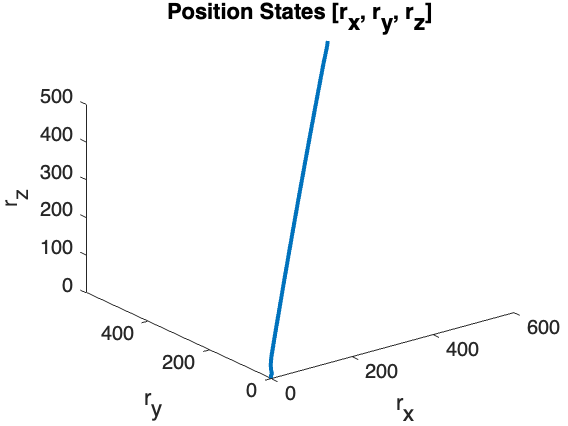


figure
plot3(xs_c(1,:),xs_c(2,:),xs_c(3,:), 'LineWidth',2);
xlabel('r_x');
ylabel('r_y');
zlabel('r_z');
title('Position States [r_x, r_y, r_z]');
figure_name = 'Constrained_position_3D_plot'; % You can change this to your desired figure name
full_path = fullfile(folder, figure_name);
saveas(gcf, full_path, 'png'); % 'png' is the file format, you can use other formats like 'jpg', 'pdf', 'fig', etc.

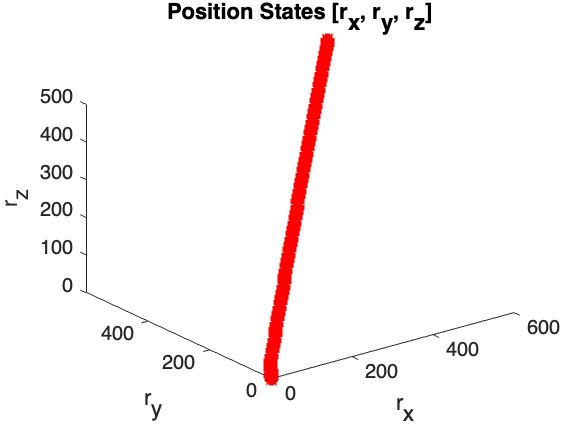


figure 
axis([0 600 0 600 0 600])
plot3(xs_c(1,:),xs_c(2,:),xs_c(3,:), 'LineWidth',2);
xlabel('r_x');
ylabel('r_y');
zlabel('r_z');
title('Position States [r_x, r_y, r_z]');
hold on 
% Set up the video writer
video_name = 'Rocket_landing_animation'; % You can change this to your desired video name
full_path = fullfile(folder, [video_name, '.mp4']);
v = VideoWriter(full_path, 'MPEG-4');
v.FrameRate = 30; % Set the frame rate (frames per second)
open(v);

for i = 1:length(xs_c(1, :))
    plot3(xs_c(1, i), xs_c(2, i), xs_c(3, i), '*r', 'LineWidth', 2.5);
    hold on;

    % Capture the current frame and add it to the video
    frame = getframe(gcf);
    writeVideo(v, frame);

    pause(0.01);
end


% Close the video writer
close(v);


## Disturbance Rejection 


N = 5 % Horizon

N = 5

[F, G] = predict_mats(A, B, N);

% cost funciton matrices
[H, L, M] = cost_mats(F, G, Q, R, P);

% pole placement
K_2 = -place(A, B, [0.01 0.01 0 0.01 0 0]);

P = dlyap((A+B*K_2)', Q+K_2'*R*K_2);
% prediction matrices
[F, G] = predict_mats(A, B, N);

% cost funciton matrices
[H, L, M] = cost_mats(F, G, Q, R, P);



% Rocket state and control input initialization
x = x0;
u = u0;
rxy_max = (500/tan(deg2rad(30)))+50

rxy_max = 916.0254


% State Constraints
xmax = [rxy_max; rxy_max; 500; 20; 20; 15];% 500m distance, 15m/s fastest z, 20m/s fastest (x,y)
xmin = [-rxy_max; -rxy_max; 0; -20; -20; -15];

Px = [eye(n); -eye(n)];
qx = [xmax; -xmin];

% input constraints
uxy_max = 12*(tan(deg2rad(10)))*4;
umax = [uxy_max ;uxy_max; 12];%fx max, fy max, fz max
umin = [-uxy_max; -uxy_max; 0];% fx min, fy min, fz min
Pu = [eye(m); -eye(m)];
qu = [umax; -umin];


k = 1;

while k<=100

w_x = 3*sin(k/50);
w_y = 3*cos(k/50);
w = [w_x w_y 0]';% wind disturbance on x, y

T_mat = [eye(6)-A -B; C zeros(6, 3)]; 
rank(T_mat);
inv_T = T_mat\[B*[w_x w_y 0 ]'; 0; 0; 0; 0; 0; 0];
x_ss = inv_T(1:6,:);
u_ss = inv_T(7:9, :);
z = x - x_ss;
v = u - u_ss;


K_2 = -place(A, B, [0.01 0.01 0 0.01 0 0]);

P = dlyap((A+B*K_2)', Q+K_2'*R*K_2);
% prediction matrices
[F, G] = predict_mats(A, B, N);

% cost funciton matrices
[H, L, M] = cost_mats(F, G, Q, R, P);

[Pc,qc,Sc] = constraint_mats(F,G,Pu,qu-Pu*u_ss,Px,qx-Px*x_ss,Px,qx-Px*x_ss);

Vopt = quadprog(H, L*z, Pc, qc+Sc*z);

% Check if Uopt is not empty before assigning values
if isempty(Vopt)
    break
end
vopt = Vopt(1:m, :);

% Update the state with disturbance
u_dr = (u_ss + vopt+ [w_x w_y 0]');
x = A*z + B*u_dr;
% Collecting Data
xs_c_dr(:, k) = x;
vs_c(:, k) = u_dr;
k = k + 1;
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because

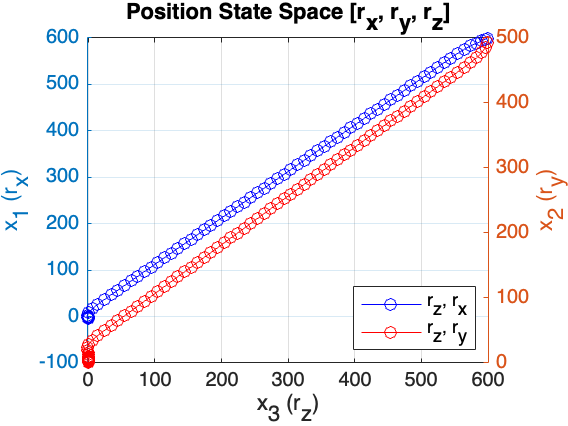


figure% Position States
yyaxis left
plot(xs_c_dr(1,:), xs_c_dr(2, :),'bo-')
ylabel('x_1 (r_x)')

yyaxis right
plot(xs_c_dr(1,:), xs_c_dr(3, :), 'ro-')
grid on
xlabel('x_3 (r_z)')
ylabel('x_2 (r_y)')
title('Position State Space [r_x, r_y, r_z]')
legend('r_z, r_x', 'r_z, r_y', location='southeast')
%maybe put the z axes as the x in both graphs
figure_name = 'DR_Constrained_position_state_space'; % You can change this to your desired figure name
full_path = fullfile(folder, figure_name);
saveas(gcf, full_path, 'png'); % 'png' is the file format, you can use other formats like 'jpg', 'pdf', 'fig', etc.

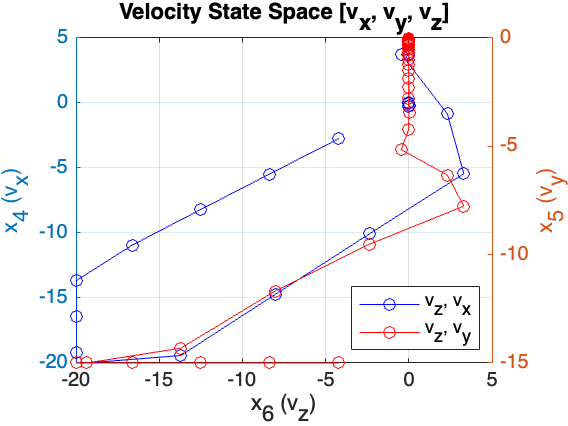


figure% Velocity States
yyaxis left
plot(xs_c_dr(4,:), xs_c_dr(5, :),'bo-')
ylabel('x_4 (v_x)')

yyaxis right
plot(xs_c_dr(4,:), xs_c_dr(6, :), 'ro-')
grid on
xlabel('x_6 (v_z)')
ylabel('x_5 (v_y)')
title('Velocity State Space [v_x, v_y, v_z]')
legend('v_z, v_x', 'v_z, v_y', location='southeast')
figure_name = 'DR_Constrained_position_state_space'; % You can change this to your desired figure name
full_path = fullfile(folder, figure_name);
saveas(gcf, full_path, 'png'); % 'png' is the file format, you can use other formats like 'jpg', 'pdf', 'fig', etc.

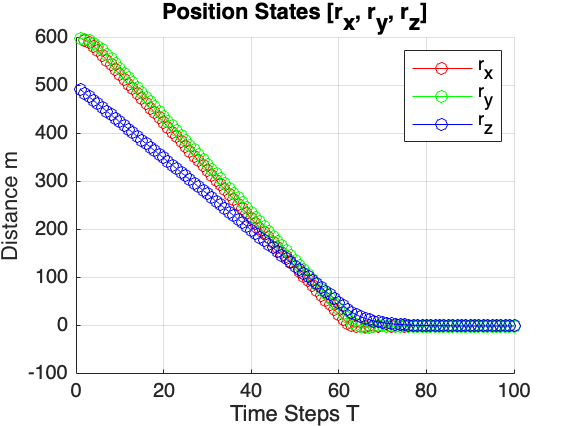


figure
hold on
grid on
plot(xs_c_dr(1,:), 'ro-')
plot(xs_c_dr(2,:), 'go-')
plot(xs_c_dr(3,:), 'bo-')

legend('r_x', 'r_y', 'r_z')
title('Position States [r_x, r_y, r_z]')
ylabel('Distance m')
xlabel('Time Steps T')
hold off
figure_name = 'DR_Constrained_position_state_plot'; % You can change this to your desired figure name
full_path = fullfile(folder, figure_name);
saveas(gcf, full_path, 'png'); % 'png' is the file format, you can use other formats like 'jpg', 'pdf', 'fig', etc.

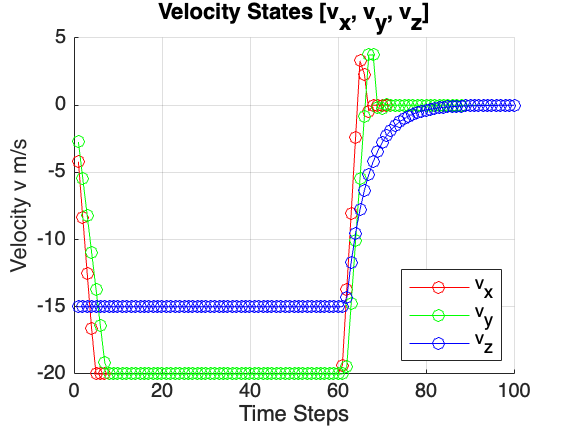


figure 
hold on
grid on
plot(xs_c_dr(4,:), 'ro-')
plot(xs_c_dr(5,:), 'go-')
plot(xs_c_dr(6,:), 'bo-')

legend('v_x', 'v_y', 'v_z', Location='southeast')
title('Velocity States [v_x, v_y, v_z]')
ylabel('Velocity v m/s')
xlabel('Time Steps')
hold off
figure_name = 'DR_Constrained_velocity_state_plot'; % You can change this to your desired figure name
full_path = fullfile(folder, figure_name);
saveas(gcf, full_path, 'png'); % 'png' is the file format, you can use other formats like 'jpg', 'pdf', 'fig', etc.

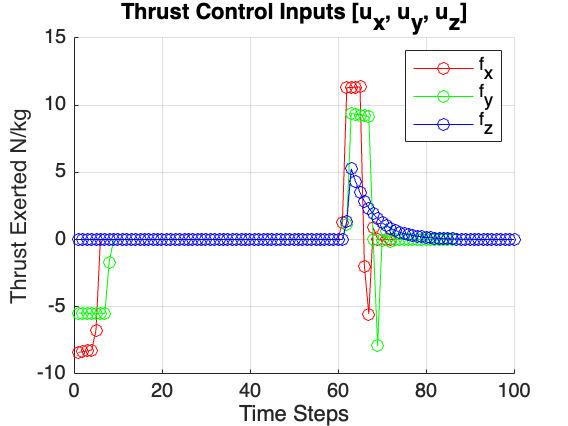


figure
hold on
grid on
plot(vs_c(1,:), 'ro-')
plot(vs_c(2,:), 'go-')
plot(vs_c(3,:), 'bo-')

legend('f_x', 'f_y', 'f_z')
title('Thrust Control Inputs [u_x, u_y, u_z]')
ylabel('Thrust Exerted N/kg')
xlabel('Time Steps')
hold off
figure_name = 'DR_Constrained_input_plot'; % You can change this to your desired figure name
full_path = fullfile(folder, figure_name);
saveas(gcf, full_path, 'png'); % 'png' is the file format, you can use other formats like 'jpg', 'pdf', 'fig', etc.

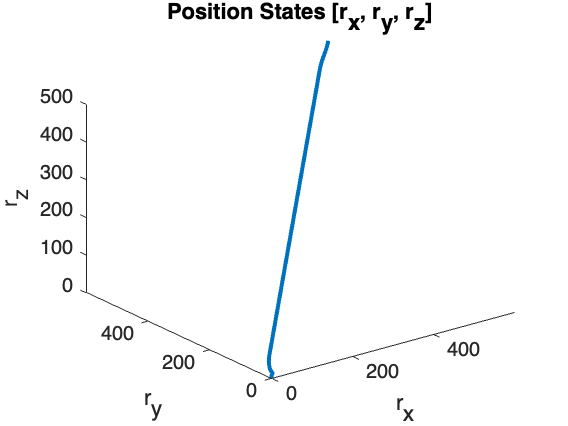


figure
plot3(xs_c_dr(1,:),xs_c_dr(2,:),xs_c_dr(3,:), 'LineWidth',2);
xlabel('r_x');
ylabel('r_y');
zlabel('r_z');
title('Position States [r_x, r_y, r_z]');
figure_name = 'DR_Constrained_position_3D_plot'; % You can change this to your desired figure name
full_path = fullfile(folder, figure_name);
saveas(gcf, full_path, 'png'); % 'png' is the file format, you can use other formats like 'jpg', 'pdf', 'fig', etc.

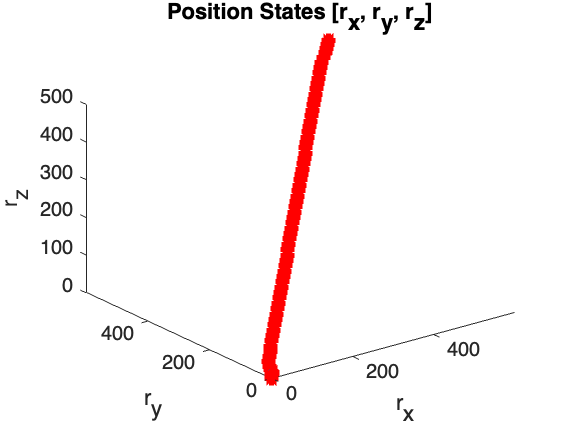


figure 
axis([0 600 0 600 0 600])
plot3(xs_c_dr(1,:),xs_c_dr(2,:),xs_c_dr(3,:), 'LineWidth',2);
xlabel('r_x');
ylabel('r_y');
zlabel('r_z');
title('Position States [r_x, r_y, r_z]');
hold on 
% Set up the video writer
video_name = 'DR_Rocket_landing_animation'; % You can change this to your desired video name
full_path = fullfile(folder, [video_name, '.mp4']);
vid = VideoWriter(full_path, 'MPEG-4');
vid.FrameRate = 30; % Set the frame rate (frames per second)
open(vid);

for i = 1:length(xs_c_dr(1, :))
    plot3(xs_c_dr(1, i), xs_c_dr(2, i), xs_c_dr(3, i), '*r', 'LineWidth', 2.5);
    hold on;

    % Capture the current frame and add it to the video
    frame = getframe(gcf);
    writeVideo(vid, frame);

    pause(0.01);
end


% Close the video writer
close(vid);